计算等离子体频率时间调制的能带结构

作者：FTT

创建时间：2024.12.12

clear
clc
close all

常量

eps0 = 8.854*1e-12; %真空介电常数
mu0 = 4*pi*1e-7; %真空磁导率
c0 = 1/sqrt(eps0*mu0); %真空光速

定义参数

omega_r0 = 1; %归一化谐振频率
omega_p0 = 3.5 * omega_r0;   % 等离子体频率
gamma = 0;
omega_m = 1.9; %调制频率
m = 0.2; %调制强度
k_r0 = omega_r0/c0; %归一化波数

静态极化率

chi = @(w) omega_p0 ^ 2 ./ (omega_r0 ^ 2 - w .^ 2 + 1i * gamma * w);

定义计算范围

krange = linspace(0.01,20,1000)*k_r0;
N = 1; %展开阶数，形成2N+1阶的矩阵
omegarange = linspace(0, omega_m, 1000); %解弗洛奎频率范围（实部）
imomegarange = 0.5*omega_m+1i*linspace(-0.005, 0.005, 1000); %解弗洛奎频率范围（虚部）
Range = 1:length(omegarange);
tor = omega_m/1000; %认为是带隙的容差
omeganum = 4; %限制最多保存的解的个数
band = nan(length(krange), omeganum+1); %非带隙内的特征频率及其对应的动量
imband = nan(length(krange), omeganum+1); %带隙内的特征频率及其对应的动量

扫k求弗洛奎频率$\omega$

for ki = 1:length(krange)

构造谐波系数矩阵


$$(k^2c_0^2-[1+\chi(\omega_n)]\omega_n^2)E_n-\frac{m}{2}\chi(\omega_{n-1})\omega_n^2E_{n-1}-\frac{m}{2}\chi(\omega_{n+1})\omega_{n}^2E_{n+1}=0$$


    M = zeros(2*N+1, 2*N+1, length(omegarange));
    error = zeros(length(omegarange), 1);
    for i = 1:2*N+1
        for j = 1:2*N+1
            n = i - (N+1); %级次
            omega_n = @(n) omegarange+n*omega_m; %谐波频率
            if i==j
                M(i, j, :) = krange(ki)^2*c0^2-(1+chi(omega_n(n))).*omega_n(n).^2;
            elseif i-j==1
                M(i, j, :) = m/2*chi(omega_n(n-1)).*omega_n(n).^2;
            elseif i-j==-1
                M(i, j, :) = m/2*chi(omega_n(n+1)).*omega_n(n).^2;
            end
        end
    end
    for g = 1:length(omegarange)
        error(g) = abs(det(M(:, :, g)));
    end
    TF = islocalmax(-error); %提取最近似解，方法是找到残差的极大值点


删除赝解

    TFindex = Range(TF);
    SoultionsError = error(TF);
    [~, I] = sort(SoultionsError); 
    if length(I) > 1
        SolutionIndex = TFindex(I(1:2)); % 只保留两个真解
    else
        SolutionIndex = TFindex(I);
    end
    
    if any(abs(omegarange(SolutionIndex)-omega_m/2) < tor) %只有有一个特征频率都在带隙内才会为正
        % 重复之前的步骤
        M = zeros(2*N+1, 2*N+1, length(imomegarange));
        error = zeros(length(omegarange), 1);
        for i = 1:2*N+1
            for j = 1:2*N+1
                n = i - (N+1); %级次
                omega_n = @(n) imomegarange+n*omega_m; %谐波频率
                if i==j
                    M(i, j, :) = krange(ki)^2*c0^2-(1+chi(omega_n(n))).*omega_n(n).^2;
                elseif i-j==1
                    M(i, j, :) = -m/2*chi(omega_n(n-1)).*omega_n(n).^2;
                elseif i-j==-1
                    M(i, j, :) = -m/2*chi(omega_n(n+1)).*omega_n(n).^2;
                end
            end
        end
        for g = 1:length(omegarange)
            error(g) = abs(det(M(:, :, g)));
        end
        TF = islocalmax(-error); %提取最近似解，方法是找到残差的极大值点
        TFindex = Range(TF);
        SoultionsError = error(TF);
        [~, I] = sort(SoultionsError); 
        if length(I) > 1
            SolutionIndex = TFindex(I(1:2)); % 只保留两个真解
        else
            SolutionIndex = TFindex(I);
        end
        imband(ki, 1:length(imomegarange(SolutionIndex))+1) = [krange(ki), imomegarange(SolutionIndex)];
    else
        band(ki, 1:length(omegarange(SolutionIndex))+1) = [krange(ki), omegarange(SolutionIndex)]; %局部赋值
        imband(ki,  1:length(omegarange(SolutionIndex))+1) = [krange(ki), zeros(1, length(omegarange(SolutionIndex)))];
    end
end

绘图

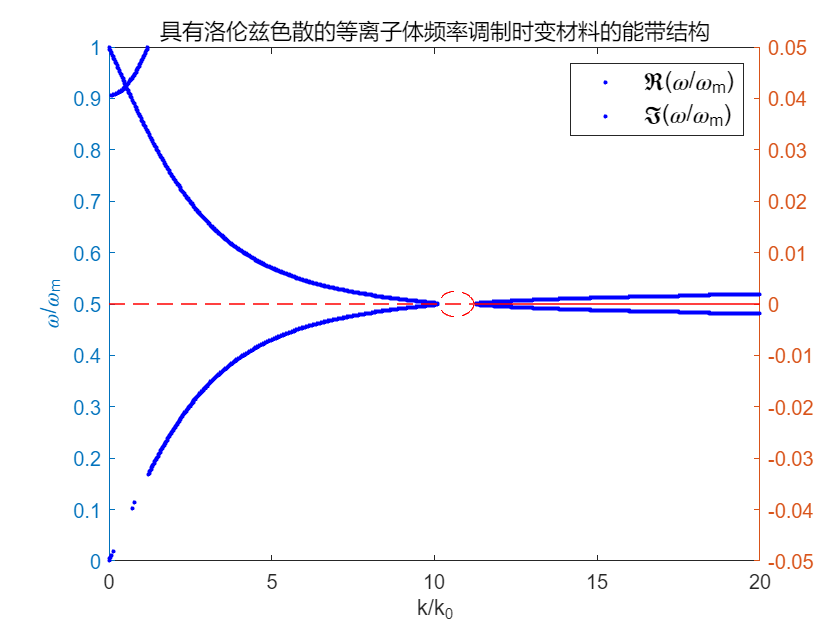

figure;
yyaxis left
plot(band(:, 1)/k_r0, band(:, 2:end)/omega_m, 'b.')
ylabel('\omega/\omega_m')
yyaxis right
plot(imband(:, 1)/k_r0, imag(imband(:, 2:end))/omega_m, 'r--')
xlabel('k/k_r_0')
ylim([-0.05 0.05])
legend({'\Re(\omega/\omega_m)', '\Im(\omega/\omega_m)'}, 'TextColor', 'black', 'FontSize', 12)
title('具有洛伦兹色散的等离子体频率调制时变材料的能带结构')